# **ASSIGNMENT 3**

# **DISTURBANCE STORM TIME INDEX PREDICTION**

clc
clear

**Import and prepare data**

fileID = fopen('omni2_26543.lst');
data = textscan(fileID,'%f');

data = reshape(data{1,1}.',[7,8760]);
data = data.';
[m, n] = size(data);

**Remove too large data**

for i = 2:m
    if data(i,5) > 5 * data(i-1,5)
        data(i,5) = data(i-1,5);
    end
end

for i = 2:m
    if data(i,6) > 5 * data(i-1,6)
        data(i,6) = data(i-1,6);
    end
end

% Driving parameter
VBs = zeros(m,1);
for i = 1:m
    if data(1,4) < 0
        VBs(i) = abs(data(i,5) * data(i,4)) / (10^3);
    else
        VBs(i) = 0
    end
end

**Model 1 (AK1)**

Dst1 = zeros(m,1);
Dst1(1) = data(1,7);
tao1 = 17;
b1 = 8.74;
c1 = 11.5;

% Correction of Dst with wind dynamic pressure
Dst_star1 = Dst1(1) - b1*sqrt(data(1,6)) + c1;
Dst1(2) = Dst_star1 - 2.47 * VBs(1) - Dst_star1/tao1;

%Calculation of Dst derivative
for i=3:m
    Dst1(i) = Dst1(i-1) - 2.47 * VBs(i) - Dst1(i-1)/tao1;
end

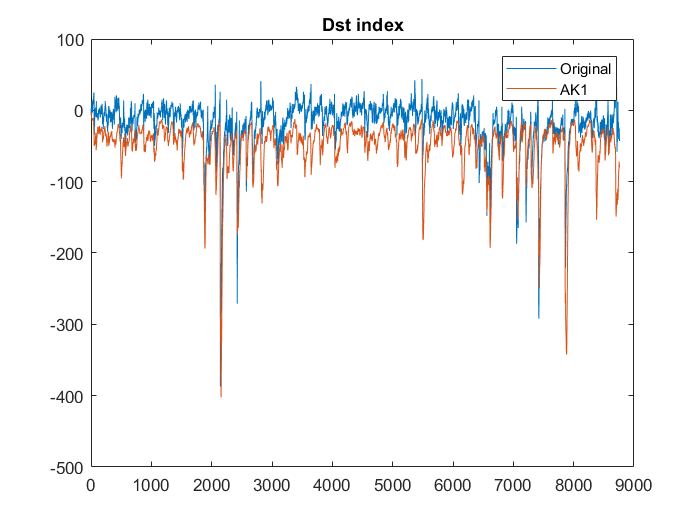

figure;
plot(data(:,7));
hold on;
plot(Dst1);
title('Dst index');
legend('Original','AK1');

**Model 2 (UCB)**

Dst2 = zeros(m,1);
Dst2(1) = data(1,7);

b2 = 15.8;
c2 = 20;

Dst_star2 = Dst2(1) - b2*sqrt(data(1,6)) + c2;
Q2 = 0;
if (VBs(1) > 0.5)
    Q2 = -4.32 * (VBs(1) - 0.5) * data(1,6)^(1/3);
end
tao2 = 7.7;
if (VBs(1) > 4)
    tao2 = 3;
end
Dst2(2) = Dst_star2 + Q2 - Dst_star1/tao2;

for i=3:m
    Q2 = 0;
    if (VBs(i) > 0.5)
        Q2 = -4.32 * (VBs(i) - 0.5) * data(i-1,6)^(1/3);
    end
    tao2 = 7.7;
    if (VBs(i) > 4)
        tao2 = 3;
    end
    Dst2(i) = Dst2(i-1) + Q2 - Dst2(i-1)/tao2;
end

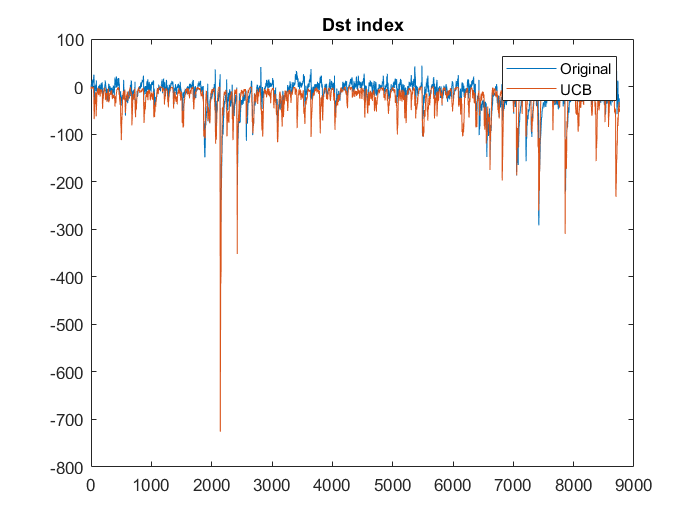

figure;
plot(data(:,7));
hold on;
plot(Dst2);
title('Dst index');
legend('Original','UCB');

**Model 3 (AK2)**

Dst3 = zeros(m,1);
Dst3(1) = data(1,7);

b3 = 7.26;
c3 = 11;

Dst_star3 = Dst3(1) - b3*sqrt(data(1,6)) + c3;
tao3 = 2.4 * exp(9.74/(4.69 + VBs(1)));
Dst3(2) = Dst_star3 - 4.4 * (VBs(1) - 0.5) - Dst_star3/tao3;

for i=3:m
    tao3 = 2.4 * exp(9.74/(4.69 + VBs(i)));
    Dst3(i) = Dst3(i-1) - 4.4 * (VBs(i) - 0.5) - Dst3(i-1)/tao3;
end

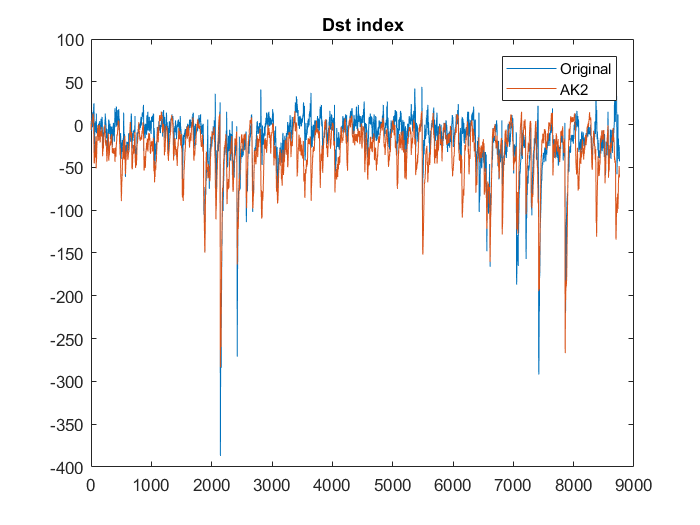

figure;
plot(data(:,7));
hold on;
plot(Dst3);
title('Dst index');
legend('Original','AK2');

**Comparison of 3 models**

% Mean-squared errors
err1 = immse(data(:,6), Dst1)

err1 = 3.8828e+03

err2 = immse(data(:,6), Dst2)

err2 = 2.2719e+03

err3 = immse(data(:,6), Dst3)

err3 = 2.0832e+03